norm=cyl06_22;
cyl=cyl06_35;
ik="VLCC_rpm20"

ik = "VLCC_rpm20"

sum1=0

sum1 = 0

sum2=0

sum2 = 0

%norm시간축 만들기
n_x=zeros(1, length(norm.ori_period))

n_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:length(norm.ori_period)
    sum1=sum1+norm.ori_period(i);
    n_x(i)=sum1;
end 

% %cyl 시간축 만들기
c_x=zeros(1, length(cyl.ori_period))

c_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:length(cyl.ori_period)
    sum2=sum2+cyl.ori_period(i);
    c_x(i)=sum2;
end 

%norm 데이터 선언
IASFR_norm=norm.ori_rpm/mean(norm.ori_rpm);
IMF_n=zeros(7,length(IASFR_norm));
IMF_n=emd(IASFR_norm,"MaxNumIMF",6);
IMF_n(:,7)=IASFR_norm;

% %cyl 데이터 선언
IASFR_cyl=cyl.ori_rpm/mean(cyl.ori_rpm);
IMF_c=zeros(7,length(IASFR_cyl));
IMF_c=emd(IASFR_cyl,"MaxNumIMF",6);
IMF_c(:,7)=IASFR_cyl;

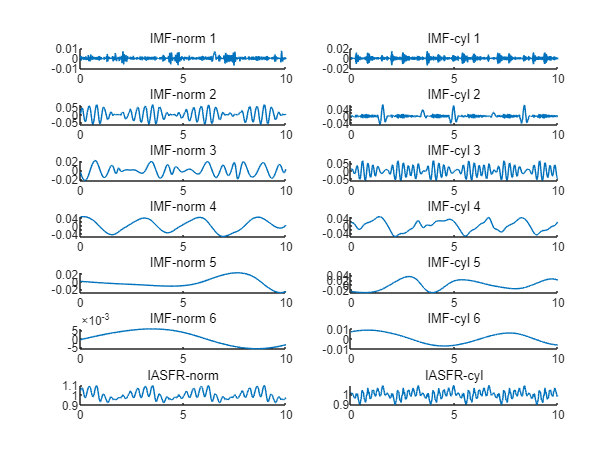

% ICA 이전 IMF, IASFR
f1=figure;
for i=1:7
    subplot(7,2,2*i-1)
    hold on
    plot(n_x,IMF_n(:,i))
    xlim([0,10])
    if i<=6
        title(['IMF-norm ',num2str(i)])
    else
        title('IASFR-norm')
    end

    subplot(7,2,2*i)
    hold on
    plot(c_x,IMF_c(:,i))
    xlim([0,10])
    if i<=6
        title(['IMF-cyl ',num2str(i)])
    else
        title('IASFR-cyl')
    end
    
    hold off
end

plot_name="ica/"+ik+"IMF.png"

plot_name = "ica/VLCC_rpm20IMF.png"

% saveas(f1,plot_name)

q=3

q = 3

tmp=rica(IMF_n,q)

tmp =   ReconstructionICA
            ModelParameters: [1×1 struct]
              NumPredictors: 7
         NumLearnedFeatures: 3
                         Mu: []
                      Sigma: []
                    FitInfo: [1×1 struct]
           TransformWeights: [7×3 double]
    InitialTransformWeights: []
    NonGaussianityIndicator: [3×1 double]


  Properties, Methods


est_n=transform(tmp,IMF_n);
% tmp2=rica(IMF_c,q)
% est_c=transform(tmp2,IMF_c);

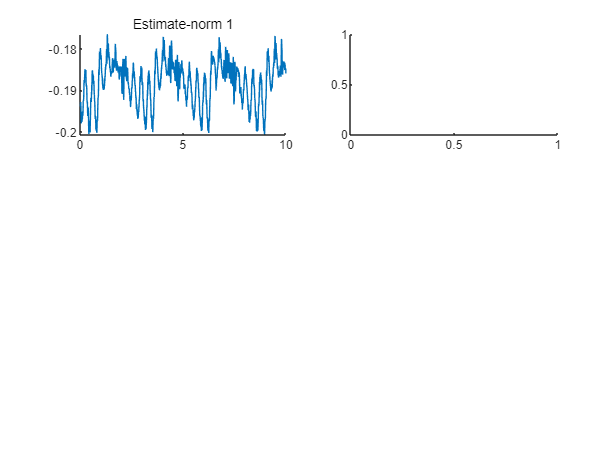

'est_c'은(는) 인식할 수 없는 함수 또는 변수입니다.

% %ICA 이후 추정된 3개
f2=figure;
for i=1:3
    subplot(3,2,2*i-1)
    hold on
    plot(n_x,est_n(:,i))
    title(['Estimate-norm ',num2str(i)])
    xlim([0,10])
    hold off

    subplot(3,2,2*i)
    hold on
    plot(c_x,est_c(:,i))
    title(['Estimate-cyl ',num2str(i)])
    xlim([0,10])
    hold off
end

plot_name="ica/"+ik+"est.png"
% saveas(f2,plot_name)

% length(est_c)




length(est_n)
k=0001


l=k+2999

[Bspec1,waxis]=BISPECD(est_n(k:l,:),1024,20,3,0);

reduce_start=(length(Bspec1)/2)-(length(Bspec1)/20);
reduce_end=(length(Bspec1)/2)+(length(Bspec1)/20);

B1_cyl_06_22=Bspec1(reduce_start:reduce_end,reduce_start:reduce_end);

% 
% save('YYYY.mat',"B1_cyl_06_22",'-append')

reduce_start


% [Bspec1,waxis]=BISPECD(est_c(k:l,:),1024,20,3,0);
% reduce_start=(length(Bspec1)/2)-(length(Bspec1)/20);
% reduce_end=(length(Bspec1)/2)+(length(Bspec1)/20);
% 
% B_cyl02_20=Bspec1(reduce_start:reduce_end,reduce_start:reduce_end);
% 
% 
% save('YYYY.mat',"B_cyl02_20",'-append')


% f3=figure;
% [Bspec1,waxis]=BISPECD(est_n(1:7000,:),1024,20,3,0)
% xlim([-0.05,0.05])
% ylim([-0.05,0.05])
% 
% % % plot_name="ica/"+ik+"Bi_norm.png"

% f4=figure;
% [Bspec2,waxis]=BISPECD(est_c(1:7000,:),1024,20,3,0)
% xlim([-0.05,0.05])
% ylim([-0.05,0.05])
% 
% % % plot_name="ica/"+ik+"Bi_cyl.png"
% % % saveas(f4,plot_name)

% length(Bspec1)

% reduce_start=(length(Bspec1)/2)-(length(Bspec1)/20)
% reduce_end=(length(Bspec1)/2)+(length(Bspec1)/20)
% reduce_Bspec_cyl06_30=Bspec1(reduce_start:reduce_end,reduce_start:reduce_end)
% reduce_axis_cyl06_30=waxis(reduce_start:reduce_end)


% save('bis_dat_cyl.mat',"reduce_Bspec_cyl06_30","reduce_axis_cyl06_30",'-append')

% [wx,waxis] = WIG3 (est_n(1:5000,1),1024)
